## Linear Discrimination

Studies the pattern classification problem with linear discrimination.

Expression: fdck = **x**^T * C^(-1) * uck - 0.5 * uck^T * C^(-1) * uck + log(P(y=ck))

where:

- ck: k class

- nck: k class length

- p: number of classes

- nT: sum of all classes length

- uck = [ **x**1k + **x**2k + ... + **x**nk ] / nck : k class mean

- C =1 / [ nt - p ] * sum (from k=1 to p) [ sum (from i=1 to nck) [ (xik - uck)^T * (xik - uck) ] ] : Matrix covariety

- P(y=ck) = nck / nT : Probability of y being k class

with:

- k = 1, 2, ..., p

% Class one
class1 = [2 3; 3 5; 5 6]

class1 =      2     3
     3     5
     5     6


% Class two
class2 = [5 2; 7 4; 8 6]

class2 =      5     2
     7     4
     8     6


% Number of classes
p = 2

p = 2

% Number of data
nt = length([class1; class2])

nt = 6

% Class means
uc1 = (1/length(class1) * sum(class1)).'

uc1 =     3.3333
    4.6667


uc2 = (1/length(class2) * sum(class2)).'

uc2 =     6.6667
    4.0000


% Prababilities of being each class
pc1 = length(class1)/nt

pc1 = 0.5000

pc2 = length(class2)/nt

pc2 = 0.5000

% Matrix covariety to the ^(-1)
sum1 = 0; sum2 = 0;
for i = 1:length(class1)
    sum1 = sum1 + ((class1(i,1:end).' - uc1) * (class1(i,1:end).' - uc1).');
    sum2 = sum2 + ((class2(i,1:end).' - uc2) * (class2(i,1:end).' - uc2).');
end
C = (1/(nt - p) * (sum1 + sum2))^(-1)

C =     4.4272   -3.6117
   -3.6117    3.2621


% Solving for the estimation lineal discrimination function
syms x1 x2
fdc1 = vpa([x1 x2] * C * uc1 - 0.5 * uc1.' * C * uc1 + log(pc1), 4)

$$fdc1 = 3.184\,x_{2}-2.097\,x_{1}-4.628$$

fdc2 = vpa([x1 x2] * C * uc2 - 0.5 * uc2.' * C * uc2 + log(pc2), 4)

$$fdc2 = 15.07\,x_{1}-11.03\,x_{2}-28.86$$

fdc = vpa(fdc2 - fdc1, 4)

$$fdc = 17.17\,x_{1}-14.21\,x_{2}-24.23$$

sf = vpa(solve(fdc, x2), 4)                 % Separation frontier

$$sf = 1.208\,x_{1}-1.705$$

% Classifying (4, 4) and (6, 4)
p1 = [4 4];
p2 = [6 4];

% If the result is negative, when replacing in the discrimination function, it means it belongs to class 1,
% If the result is positive, it means it belongs to class 2
round(subs(fdc, [x1 x2], p1), 2)

$$ans = -12.43$$

round(subs(fdc, [x1 x2], p2), 2)

$$ans = 21.9$$

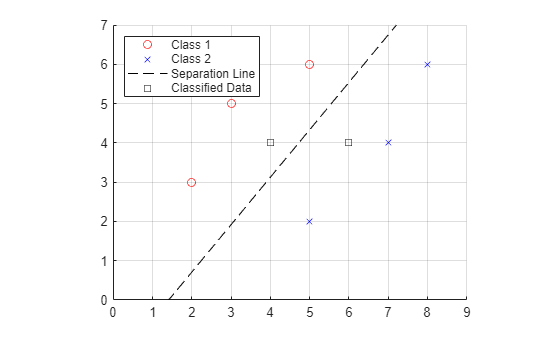

% Ploting data
figure;
hold on;
plot(class1(1:end,1).', class1(1:end,2).', 'ro');
plot(class2(1:end,1).', class2(1:end,2).', 'bx');
plot([0 9], [subs(sf, x1, 0), subs(sf, x1, 9)], 'k--');
plot([4 6], [4 4], 'ksquare');
axis equal; grid on; 
xlim([0 9]); ylim([0 7]); xticks(0:9); yticks(0:7);
legend('Class 1', 'Class 2', 'Separation Line', 'Classified Data', 'Location','northwest');
hold off;

### Examples

Example 1

Solve for:

- Linear discrimination functions fdc1, fdc2, fdc3

- Solve for separation frotiers

- Determine what class do (5, 3), (7, 7) and (7, 4) belong to

c1 = [2 3; 2 5];
c2 = [5 8; 7 8];
c3 = [9 4; 9 6];
[fdck, sfi] = Linear_discrimination(c1, c2, c3);

% Linear discrimination functions
fdck

fdck = 3×1 cell array
    {[3.0*x1 + 3.0*x2 - 10.1   ]}
    {[9.0*x1 + 6.0*x2 - 52.1   ]}
    {[13.5*x1 + 3.75*x2 - 71.22]}


sfi

sfi = 3×1 cell array
    {[4.5*x1 - 2.25*x2 - 19.12 ]}
    {[10.5*x1 + 0.75*x2 - 61.13]}
    {[6.0*x1 + 3.0*x2 - 42.0   ]}


% Solving for separation frotiers
sf = {};
sf{1} = vpa(solve(sfi{1}, x2), 4);
sf{2} = vpa(solve(sfi{2}, x2), 4);
sf{3} = vpa(solve(sfi{3}, x2), 4);

% Classifying given points
p1 = [5 3];
p2 = [7 7];
p3 = [7 4];

% Another way of classifying:
% If the result is negative, it means that the data point is to the left of the frontier
% And if the result is positive, it means that the data point is to the right of the frontier

% (5, 3) - Class 1
vpa(subs(sfi{3}, [x1 x2], p1), 4)           % Left

$$ans = -3.0$$

vpa(subs(sfi{2}, [x1 x2], p1), 4)           % Left

$$ans = -6.375$$

vpa(subs(sfi{1}, [x1 x2], p1), 4)           % Left

$$ans = -3.375$$

% (7, 7) - Class 2
vpa(subs(sfi{3}, [x1 x2], p2), 4)           % Right

$$ans = 21.0$$

vpa(subs(sfi{2}, [x1 x2], p2), 4)           % Right

$$ans = 17.62$$

vpa(subs(sfi{1}, [x1 x2], p2), 4)           % Left

$$ans = -3.375$$

% (7, 4) - Class 3
vpa(subs(sfi{3}, [x1 x2], p3), 4)           % Right

$$ans = 12.0$$

vpa(subs(sfi{2}, [x1 x2], p3), 4)           % Right

$$ans = 15.37$$

vpa(subs(sfi{1}, [x1 x2], p3), 4)           % Right

$$ans = 3.375$$

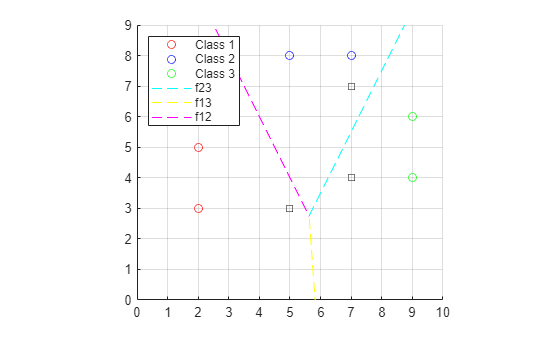

% Ploting data
figure;
hold on;
plot(c1(1:end,1).', c1(1:end,2).', 'ro');
plot(c2(1:end,1).', c2(1:end,2).', 'bo');
plot(c3(1:end,1).', c3(1:end,2).', 'go');
plot([5.63 10], [subs(sf{1},x1,5.63), subs(sf{1},x1,10)], 'c--');
plot([5.63 5.9], [subs(sf{2},x1,5.63), subs(sf{2},x1,5.9)], 'y--');
plot([0 5.63], [subs(sf{3},x1,0), subs(sf{3},x1,5.63)], 'm--');
plot([5 7 7], [3 7 4], 'squarek');
axis equal; grid on; 
xlim([0 10]); ylim([0 9]); xticks(0:10); yticks(0:9);
legend('Class 1', 'Class 2', 'Class 3', 'f23', 'f13', 'f12', 'Location','northwest');
hold off;